# toy RobustPCA example: artificial data

addpath('../');

M = 50; N = 100;  % data matrix size
toy_rank = 5;     % rank of the low-rank component
toy_card = 0.20;  % cardinality of the sparse component

% generate random basis vectors
r = {};%【这是在定义啥？】
for i = (1:toy_rank)
    r{i} = rand(1,N);%1×N随机矩阵
end

% stack them into a matrix
X0 = zeros(M,N);%50×100
for i = (1:M)
    ind = floor(rand*toy_rank + 1);%【rand怎么跑出来的】
    X0(i,:) = r{ind};
end
X0 = X0 - mean(X0(:));

% add some sparse noise
X1 = sign(rand(M,N) - 0.5);
X1 = X1 .* (rand(M,N) < toy_card);
X = X0 + X1;

% run Robust PCA and show results
[L, S] = RobustPCA(X);

iter: 0001	err: 0.115706	rank(L): 50	card(S): 1122
iter: 0010	err: 0.012515	rank(L): 37	card(S): 2020
iter: 0020	err: 0.002914	rank(L): 5	card(S): 1226
iter: 0030	err: 0.000123	rank(L): 5	card(S): 1128
iter: 0040	err: 0.000019	rank(L): 5	card(S): 1121
iter: 0050	err: 0.000005	rank(L): 5	card(S): 1123
iter: 0060	err: 0.000002	rank(L): 5	card(S): 1123
iter: 0066	err: 0.000001	rank(L): 5	card(S): 1123


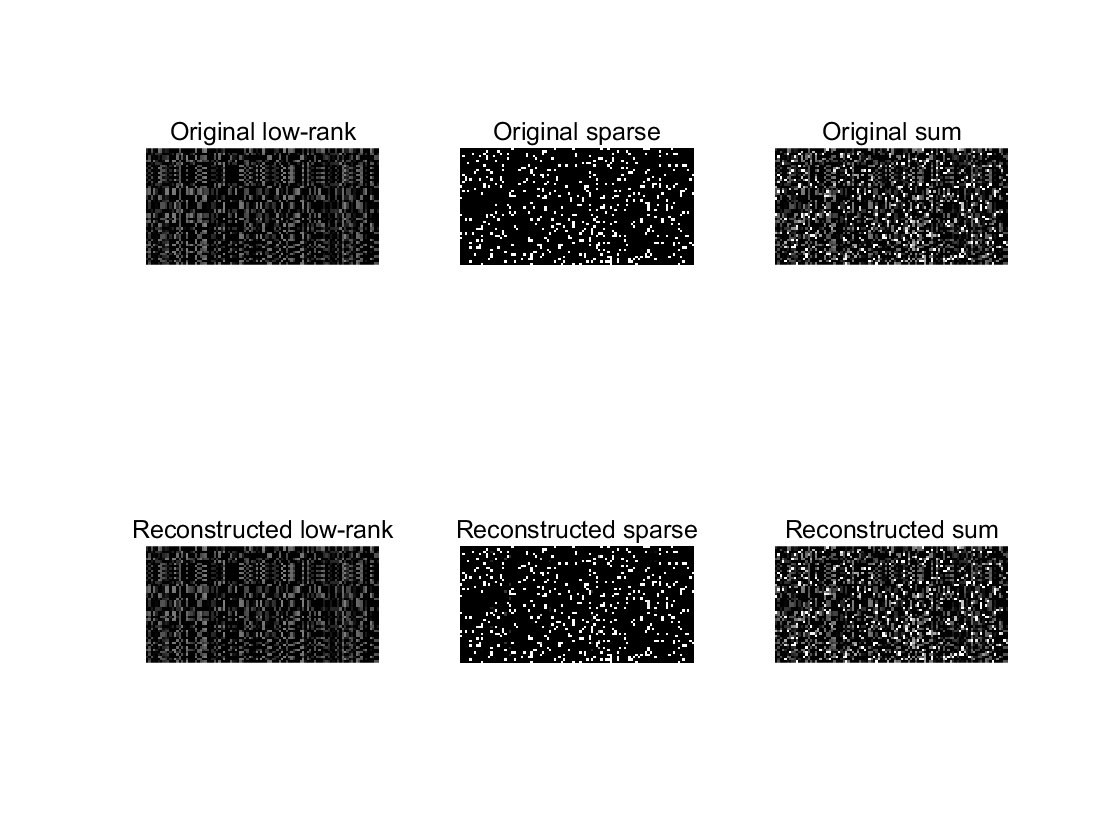


figure;
subplot(2,3,1), imshow(X0), title('Original low-rank')
subplot(2,3,2), imshow(X1), title('Original sparse')
subplot(2,3,3), imshow(X), title('Original sum')
subplot(2,3,4), imshow(L), title('Reconstructed low-rank')
subplot(2,3,5), imshow(S), title('Reconstructed sparse')
subplot(2,3,6), imshow(L+S), title('Reconstructed sum')


fprintf(1, 'rank(L) = %d\n', rank(L));

rank(L) = 5


fprintf(1, 'nnz(S)/(M*N) = %d%%\n', round(100*nnz(S)/length(S(:))));

nnz(S)/(M*N) = 22%
